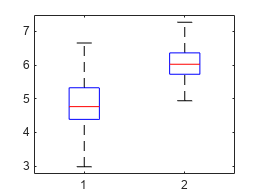

rng(2023)
d1=5+randn(50,1);
d2=6+.5*randn(50,1);
%a 
boxplot([d1,d2])

%b
clas = [zeros(1, length(d1)), ones(1, length(d2))]

clas =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


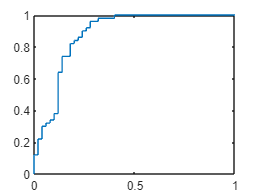

[tpr,fpr,cuts] = roc(clas,[d1',d2']);
plot(fpr,tpr)


dfpr=(fpr(2:end)-fpr(1:(end-1)))/2;
atpr=(tpr(2:end)+tpr(1:(end-1)))/2;
auc=sum(dfpr.*atpr)

auc =        0.4398